clearvars
format long

# Research Techniques Project: Unit test

This is a unit test using the KIC 11924311 source since it has documented periodicity

## Data Exploration

In this section we are exploring and displaying the raw data so it can be used for analysis

opts = detectImportOptions("KIC_11924311_Photometry.txt");
opts.DataLines = 2;
%opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableNames = {'Time','Filter','Flux','error'};

"time" is in the units of days and "flux" is "rel_flux_T1" from AstroImageJ outputs. 

opts.VariableTypes = {'double','char','double','double'};
KIC_11924311 = rmmissing(readtable("KIC_11924311_Photometry.txt",opts)); %the matrix data of the text file
preview("KIC_11924311_Photometry.txt",opts)

ans = 8×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'B'}     0.67636    0.002971
    57985    {'B'}      0.6859       0.003
    57985    {'B'}     0.68148    0.002991
    57985    {'B'}     0.69522    0.003017
    57985    {'B'}     0.69789    0.003033
    57985    {'B'}     0.69235    0.003006
    57985    {'B'}     0.70017    0.003037
    57985    {'B'}     0.69389    0.002996


whos KIC_11924311

  Name                 Size             Bytes  Class    Attributes

  KIC_11924311      2957x4             386047  table              



filters = unique(KIC_11924311{:,2},'stable');
poscount = [1 0 0 0 0];
temp = zeros(1,4);
 
count = 1;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;
end
KICB = KIC_11924311(poscount(count):poscount(count+1)-1,:)

KICB = 349×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'B'}     0.67636    0.002971
    57985    {'B'}      0.6859       0.003
    57985    {'B'}     0.68148    0.002991
    57985    {'B'}     0.69522    0.003017
    57985    {'B'}     0.69789    0.003033
    57985    {'B'}     0.69235    0.003006
    57985    {'B'}     0.70017    0.003037
    57985    {'B'}     0.69389    0.002996
    57985    {'B'}     0.70967    0.003057
    57985    {'B'}     0.70263    0.003026
    57985    {'B'}     0.70944    0.003056
    57985    {'B'}     0.71281    0.003053
    57985    {'B'}     0.71539    0.003062
    57985    {'B'}     0.71921    0.003146
    57985    {'B'}     0.72563    0.003272
    57985    {'B'}     0.72387    0.003132


count = 2;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;
end
KICV = KIC_11924311(poscount(count):poscount(count+1)-1,:)

KICV = 350×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'V'}     0.72608     0.00284
    57985    {'V'}     0.72676    0.002841
    57985    {'V'}     0.72877    0.002839
    57985    {'V'}     0.73102    0.002843
    57985    {'V'}     0.73477    0.002852
    57985    {'V'}     0.74009    0.002877
    57985    {'V'}     0.74063    0.002859
    57985    {'V'}     0.74478    0.002875
    57985    {'V'}     0.74259    0.002859
    57985    {'V'}     0.74714    0.002874
    57985    {'V'}     0.74956     0.00288
    57985    {'V'}     0.75451    0.002899
    57985    {'V'}     0.76023    0.002918
    57985    {'V'}     0.76028     0.00292
    57985    {'V'}     0.75968    0.002942
    57985    {'V'}     0.76063    0.003006


count = 3;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;
end
KICR = KIC_11924311(poscount(count):poscount(count+1)-1,:)

KICR = 350×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'R'}     0.74284    0.003048
    57985    {'R'}     0.74456    0.003066
    57985    {'R'}     0.75455     0.00309
    57985    {'R'}     0.75485    0.003076
    57985    {'R'}     0.75807    0.003077
    57985    {'R'}     0.76211    0.003086
    57985    {'R'}     0.76861     0.00311
    57985    {'R'}      0.7702    0.003132
    57985    {'R'}     0.76533    0.003096
    57985    {'R'}     0.76892    0.003097
    57985    {'R'}      0.7678     0.00309
    57985    {'R'}     0.77622     0.00313
    57985    {'R'}     0.78119    0.003148
    57985    {'R'}     0.78604    0.003168
    57985    {'R'}      0.7865    0.003223
    57985    {'R'}     0.79157    0.003204


count = 4;
poscount(count+1) = poscount(count);
while char(filters(count))==char(KIC_11924311{poscount(count+1),2}) 
    poscount(count+1) = poscount(count+1) + 1;
end
KICI = KIC_11924311(poscount(count):poscount(count+1)-1,:)

KICI = 350×4 table
    Time     Filter     Flux       error  
    _____    ______    _______    ________

    57985    {'I'}     0.76493    0.005148
    57985    {'I'}     0.78074    0.005261
    57985    {'I'}      0.7751    0.005121
    57985    {'I'}     0.77435    0.005184
    57985    {'I'}     0.78234    0.005198
    57985    {'I'}     0.78959    0.005184
    57985    {'I'}     0.78702    0.005132
    57985    {'I'}     0.78799    0.005191
    57985    {'I'}     0.79257    0.005159
    57985    {'I'}     0.79262    0.005145
    57985    {'I'}     0.79892    0.005188
    57985    {'I'}     0.80309    0.005174
    57985    {'I'}     0.81054    0.005176
    57985    {'I'}     0.80187     0.00522
    57985    {'I'}     0.80033     0.00521
    57985    {'I'}     0.80613    0.005146


To understand the nature of the data, it is important to visualise it. This example is from the B filter. Error is ignored for the analysis in this project.

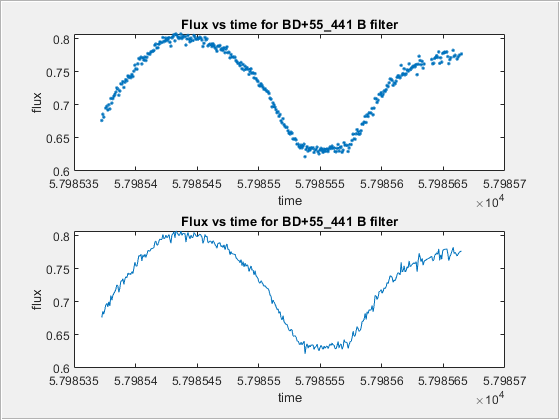

hf_sub(1) = figure(1);
hp(1) = uipanel('Parent',hf_sub(1),'Position',[0 0 1 1]);
subplot(2,1,1,'Parent',hp(1));
plot(KICB.Time,KICB.Flux,'.')
title('Flux vs time for BD+55\_441 B filter');
xlabel('time'),ylabel('flux');
subplot(2,1,2,'Parent',hp(1));
plot(KICB.Time,KICB.Flux),title('Flux vs time for BD+55\_441 B filter')
xlabel('time');
ylabel('flux');